# Gamma Calibration

## Goal

Find a good configuration for the gamma block regs, i.e, scale offset and lut.

Good means the following - 

- All calibrated units should have the same IR response for the same scene. The confidence calculation and the template configuration depend on it (and maybe the RX delay even though it doesn't sound right to me).

- The IR response should be suited for use in the following blocks. Like confidence, templates and RX delay.  

- The IR should be visually satisfying and correctable by the Gamma block in the JFIL.

## Background

When capturing a scene of lineary varing color, the resulting IR image will not maintain the linearity of the colors. This effect is caused by the nonlinear response of the sensor to different colors. The following figure shows the effect the gamma correction block should have on an image: 

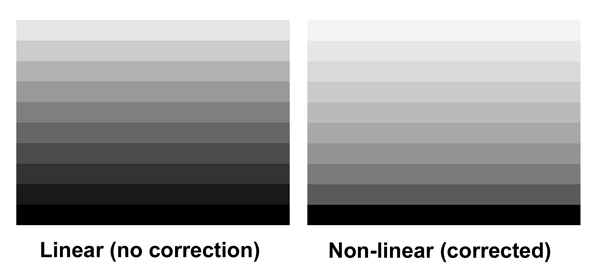

The relevant block in the algo pipe is the DIGG. The operation will be done using a shift, scale and a lut.

**Method**

The calibration process will be easy if it will be done with the normal calibration target:

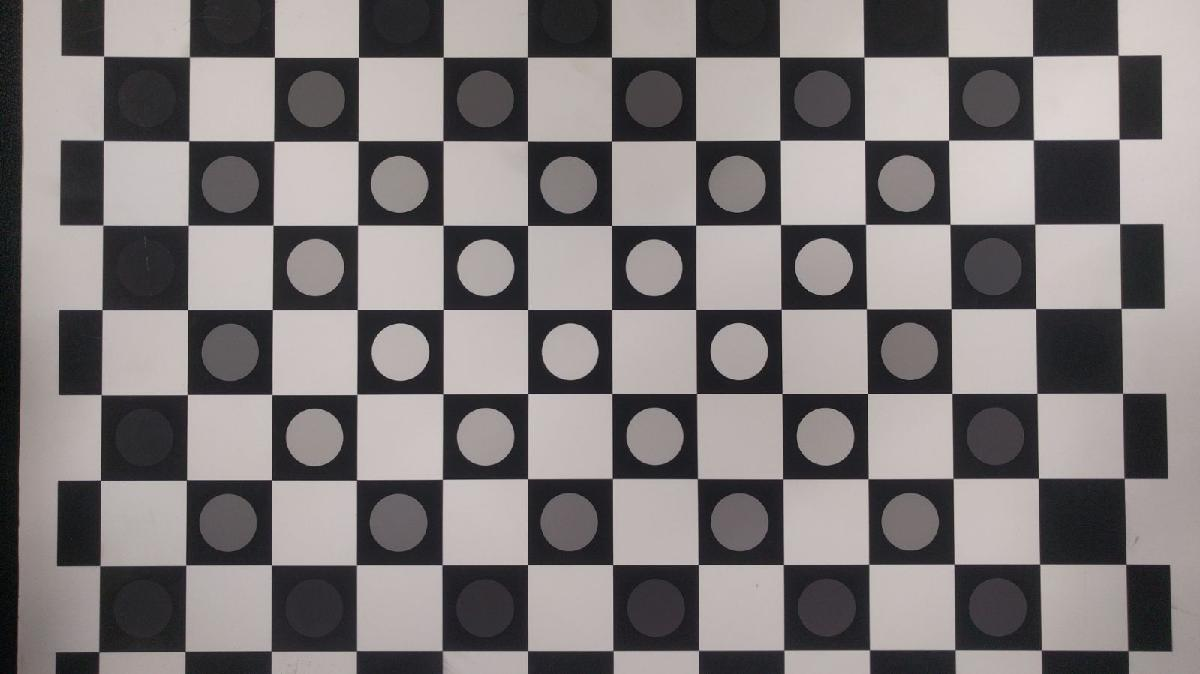

The squares albedo are black and white. The circles (inside the black squares) albedo varies.

For starter, it is interesting to see how different is the intensity curve of the 48 black squares for different cameras. I used nexus 5 cellular device camera, a PointGray IR camera and IVCAM 2. 

For each capture, I find the centers of all black squares, sorted their intensity and plotted their values:


I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBFar.jpg'); 

Undefined function 'readGrayImage' for input arguments of type 'char'.

[~,ccBlackPhoneFar] = DetectBlackCBPointsAndSortedValues(I);


I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBClose.jpg');
[~,ccBlackPhoneClose] = DetectBlackCBPointsAndSortedValues(I);

I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBivcam.jpg');
[~,ccBlackIvcam] = DetectBlackCBPointsAndSortedValues(I);

I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBpointgray.pgm');
[~,ccBlackPG] = DetectBlackCBPointsAndSortedValues(I);

I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\PGStreamNoLightsMax.pgm');
[~,ccBlackPGNoLightsTester] = DetectBlackCBPointsAndSortedValues(I);

I = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBTesterFarIvcam.tif');
[~,ccBlackIvcamNoLightsTester] = DetectBlackCBPointsAndSortedValues(I);


figure
plot([ccBlackPhoneFar,ccBlackPhoneClose,ccBlackIvcam,ccBlackPG,ccBlackPGNoLightsTester,ccBlackIvcamNoLightsTester],'-o')
title('Intensity per black square')
legend({'PhoneFar','PhoneClose','Ivcam','PG','PGTester','IVCAMTeser'},'location','northwest');

The IVCAM IR values spans most of the range ([min,max] are [50,250]). While the phone values are almost monotonically increasing and are close to linear, the ivcam and PG recordings seems noisy. The are some reasons that contribue to that phenomenon:

- The phone camera image has already gone through gamma correction. 

- The phone camera probably compensates for [Vignetting](https://en.wikipedia.org/wiki/Vignetting) while ivcam doesn't (The cos^4 illumination fallout).

A suggested approach for calibrating the GAMMA:

- Take the PG image. Use 3d interpolation (x,y,ir) to identify the mapping between the black and white points to their minimal and maximal values. Apply to all pixels.

- Take the IVCAM image. Do the same.  

- Define the scale,shift and lut so each color in the normalized images match. The normalization purpose is to minimize the effect the different lighting (and maybe position) has on the IR images.

## Gamma Correcting

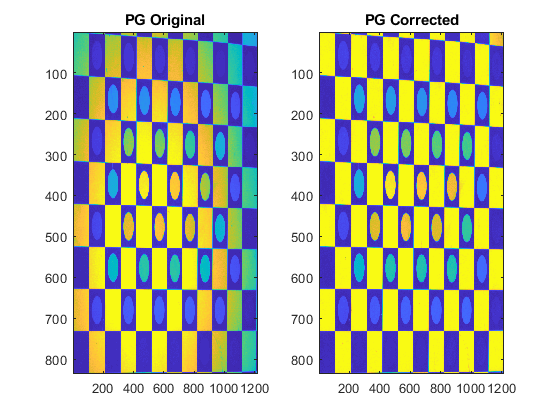

% Load Point Gray Image
Ipg = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBpointgray.pgm');
Ipg = rot90(Ipg,2);
% Get the corners of all squares. For each square, get the pixel values close to the four corners and also the center value for the white squares.  
[ newI,oldV,newV ] = correctCheckerboard( Ipg );
% Load IVCAM Image
Iivcam = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBTesterFarIvcam.tif');
% Get the corners of all squares. For each square, get the pixel values close to the four corners and also the center value for the white squares.  
[ newIivcam,oldVivcam,newVivcam ] = correctCheckerboard( Iivcam );
figure
subplot(1,2,1);
imagesc(oldV), title('PG Original');
subplot(1,2,2);
imagesc(newV), title('PG Corrected');

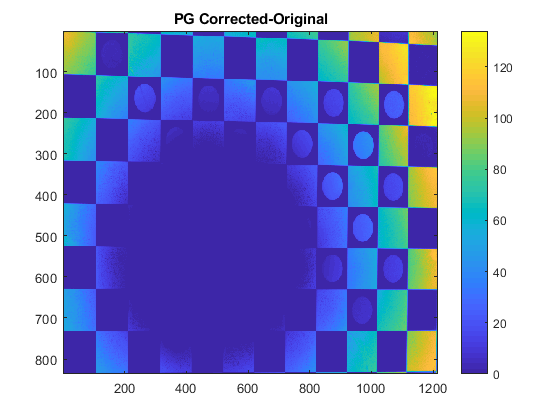

figure;
imagesc(newV-oldV),title('PG Corrected-Original'),colorbar;

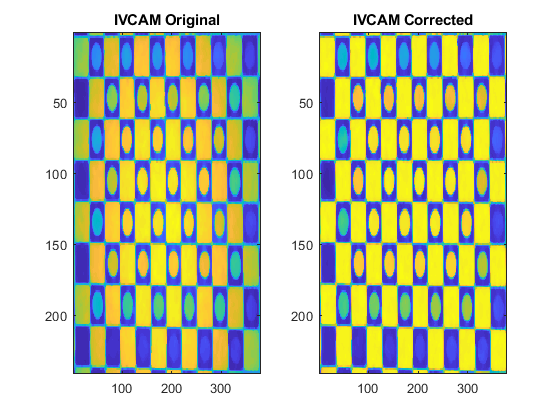


figure
subplot(1,2,1);
imagesc(oldVivcam), title('IVCAM Original');
subplot(1,2,2);
imagesc(newVivcam), title('IVCAM Corrected');

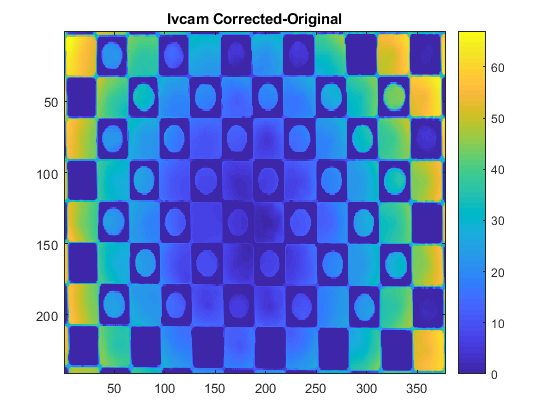

figure;
imagesc(newVivcam-oldVivcam),title('Ivcam Corrected-Original'),colorbar;

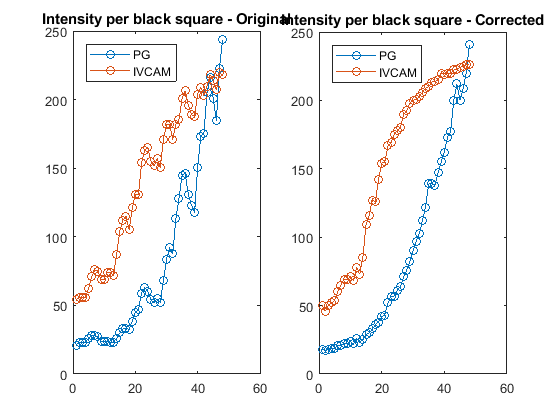


% Now let us have a look at the IR curve of the circles before and after the correction

[~,cpIvcam] = DetectBlackCBPointsAndSortedValues(Iivcam);
[~,cpPG] = DetectBlackCBPointsAndSortedValues(Ipg);
[~,cpIvcamPost] = DetectBlackCBPointsAndSortedValues(newIivcam);
[~,cpPGPost] = DetectBlackCBPointsAndSortedValues(newI);

subplot(1,2,1)
plot([cpPG,cpIvcam],'-o'),title('Intensity per black square - Original')
legend({'PG','IVCAM'},'location','northwest');
subplot(1,2,2)
plot([cpPGPost,cpIvcamPost],'-o'),title('Intensity per black square - Corrected')
legend({'PG','IVCAM'},'location','northwest');

**Experiments**

**TPS scale and shift robustness**

I shall correct an image to the min and max value in the checkerboard. Then I shall correct an image to 0 and 255 from the beginning and compare the resultinging IR curves. For the comparission to make sense I linearly transformed the regular curve so its maximal and minimal value will align with the formost mode. 

Ipg = readGrayImage('\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\CBpointgray.pgm');
Ipg = rot90(Ipg,2);
% Get the corners of all squares. For each square, get the pixel values close to the four corners and also the center value for the white squares.  

[ I,~,~ ] = correctCheckerboard( Ipg,[10 255]);
[~,ccStreched] = DetectBlackCBPointsAndSortedValues(I);

[ I,~,~ ] = correctCheckerboard( Ipg );
[~,ccRegular] = DetectBlackCBPointsAndSortedValues(I);
ccRegular = ((ccRegular-min(ccRegular))/(max(ccRegular)-min(ccRegular)))*(max(ccStreched)-min(ccStreched))+min(ccStreched);

plot([ccRegular,ccStreched],'-o'),title('Intensity per black square')
legend({'Regular(min,max)','Strected(0,255)'},'location','northwest');

The resulting IR curves are almost identical. The conclusion is that we can linearly transform the result of the correcting method to a predifined range, and the operation will be equivalant to using different ground truth values for the checkerboard white and black squares. Not really sure where I was going with this.....

**Same Images with Different Lighting**

I captured twice the same scene, once with only neon light and once with both the neon light and my cellphone camera. For each capture I took 30 images and averaged them:

N = 30;
dirName = '\\tmund-MOBL1.ger.corp.intel.com\C$\git\ivcam2.0\scripts\calibScripts\GammaCalib\PGCaptures';
prefixNeon = 'PGNeonOnly_2018-02-28-145305-';
prefixPhone = 'PGNeonAndPhoneFromRight_2018-02-28-145446-';
suffix = '.pgm';
pgNeon = rot90(avgStream(dirName,prefixNeon,suffix,N),2);
pgPhone = rot90(avgStream(dirName,prefixPhone,suffix,N),2);

[~,ccNeonOrig] = DetectBlackCBPointsAndSortedValues(pgNeon);
[pgNeonCorr,~,~ ] = correctCheckerboard( pgNeon);
[~,ccNeonCorr] = DetectBlackCBPointsAndSortedValues(pgNeonCorr);

[~,ccPhoneOrig] = DetectBlackCBPointsAndSortedValues(pgPhone);
[pgPhoneCorr,~,~ ] = correctCheckerboard( pgPhone);
[~,ccPhoneCorr] = DetectBlackCBPointsAndSortedValues(pgPhoneCorr);

subplot(1,2,1)
plot([ccNeonOrig,ccPhoneOrig],'-o'),title('Intensity per black square - Original')
legend({'Neon','Neon+Phone'},'location','northwest');
subplot(1,2,2)
plot([ccNeonCorr,ccPhoneCorr],'-o'),title('Intensity per black square - Corrected')
legend({'Neon','Neon+Phone'},'location','northwest');

On can see that the correcting procedure isn't oblivious to the phone's flashlight. Which means we can't even trust that is compensates for the fact that the neon is located at the bottom of the tester. On the other hand, the corrected IR values behave nicely.

**Same Scene with Different Camera**

The pg and ivcam images were taken from about the same position. 